clc;
clear;
close all;

% material = ["bottle", "cable", "capsule", "carpet", "grid", "hazelnut", "leather", "metal_nut", "pill", "screw", "tile", "toothbrush", "transistor", "wood", "zipper"];

material = ["hazelnut"];
extractor = cell(length(material));

% Create structs for each element with names and multiple imds
for counter = 1:length(material)
    element(counter).name = material(counter);
    element(counter).imdsMask = [imageDatastore("00_data/"+material(counter)+"/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];
    element(counter).imdsAllImages = imageDatastore("00_data/"+material(counter)+"/test/","FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");

    wrongImages = {};
    allImages = {};
    for i = 1:length(element(counter).imdsAllImages.Files)
        if element(counter).imdsAllImages.Labels(i)=="good"
            wrongImages{end+1,1} = string(element(counter).imdsAllImages.Files(i));
        end
        allImages{end+1,1} = string(element(counter).imdsAllImages.Files(i));
    end
    
    for k = 1:length(allImages)
        for j = 1:length(wrongImages)
            if k>length(allImages)
                break
            end
            if string(allImages(k,1))==string(wrongImages(j,1))
                allImages(k,:) = [];
            end
        end
    end
    element(counter).imageFilename = allImages;

end



data(counter).material = material(counter);
data(counter).imds = [imageDatastore(["00_data/"+material(counter)+"/train/","00_data/"+material(counter)+"/test/"], "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];

for picture = 1:length(data(counter).imds)
    groundtruth = imageDatastore("00_data/"+material(counter)+"/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");

end



clc;
clear;
close all;

imdsMask = imageDatastore("00_data/bottle/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");
imdsAllImages = imageDatastore("00_data/bottle/test/","FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");

wrongImages = {};
allImages = {};
for i = 1:length(imdsAllImages.Files)
    if imdsAllImages.Labels(i)=="good"
        wrongImages{end+1,1} = string(imdsAllImages.Files(i));
    end
    allImages{end+1,1} = string(imdsAllImages.Files(i));
end

for k = 1:length(allImages)
    for j = 1:length(wrongImages)
        if k>length(allImages)
            break
        end
        if string(allImages(k,1))==string(wrongImages(j,1))
            allImages(k,:) = [];
        end
    end
end
     

error = {};

for size = 1:length(imdsMask.Files)
    region = regionprops(imread(imdsMask.Files{size,1}));
    region_table = struct2table(region);
    for field = 1:length(region)
        if region(field).Area > 0
            error{end+1,1} = region(field).BoundingBox;
        end
    end
    maskFilename(size, 1) = imdsMask.Files(size);
end
data = table(error);
data.maskFilename = maskFilename;
data.imageFilename = allImages;

rng(0);
shuffledData = data;
shuffledIdx = randperm(height(shuffledData));
shuffledData = shuffledData(shuffledIdx,:);

% Train Test Split
cv = cvpartition(height(shuffledData),'HoldOut',0.2);
idx = cv.test;
trainingDataTbl = shuffledData(~idx,:);
testDataTbl  = shuffledData(idx,:);

imdsTrain = imageDatastore(cellstr(trainingDataTbl{:,'imageFilename'}));
imdsTest = imageDatastore(cellstr(testDataTbl{:,'imageFilename'}));

bldsTrain = boxLabelDatastore(trainingDataTbl(:,'error'));
bldsTest = boxLabelDatastore(testDataTbl(:,'error'));

trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

imds = imdsAllImages;
blds = boxLabelDatastore(data(:,"error"));
ds = combine(imds, blds);

inputSize = [224 224 3];
preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data,inputSize));
numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData,numAnchors);
featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
numClasses = 1;


lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

options = trainingOptions('sgdm', ...
      'MiniBatchSize', 1, ...
      'InitialLearnRate', 1e-3, ...
      'MaxEpochs', 7, ...
      'VerboseFrequency', 200, ...
      'CheckpointPath', tempdir);

detector = trainFasterRCNNObjectDetector(ds, lgraph, options, ...
        'NegativeOverlapRange',[0 0.3], ...
        'PositiveOverlapRange',[0.6 1]);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* error

Training on single GPU.
Initializing input data normalization.
|=============================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |      Rate       |
|=============================================================================================================================================|
|       1 |           1 |       00:00:18 |       2.0726 |       10.50% |         0.15 |           26.56% |             0.69 |          0.0010 |
|       4 |         200 |       00:37:54 |       0.6776 |  

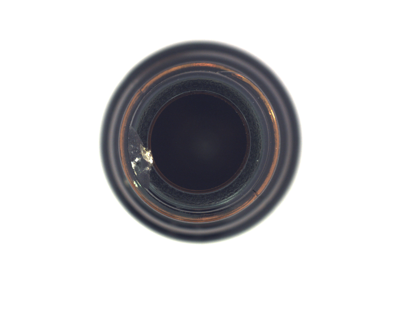

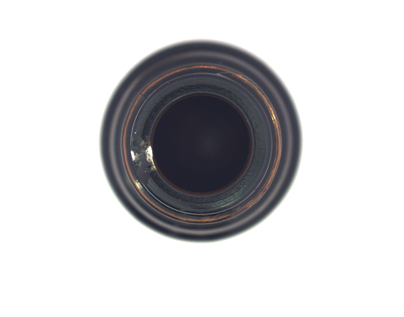

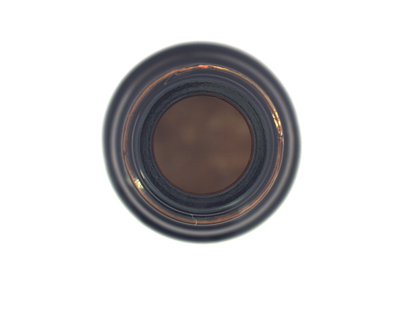

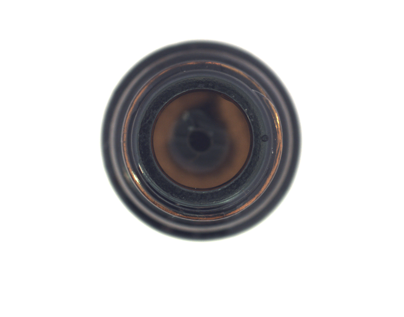

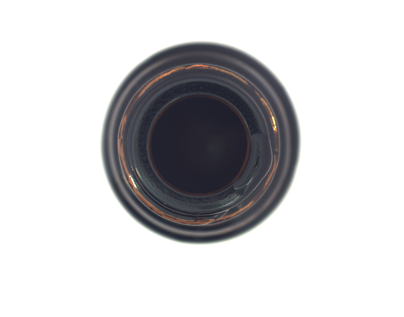

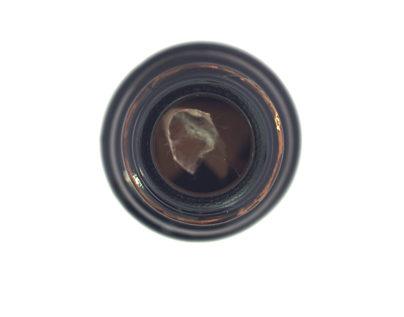

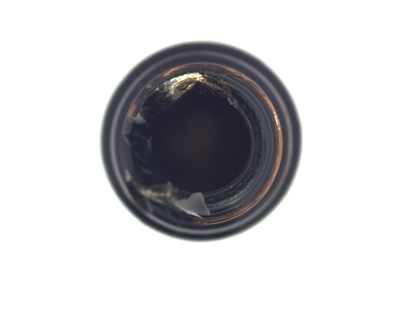

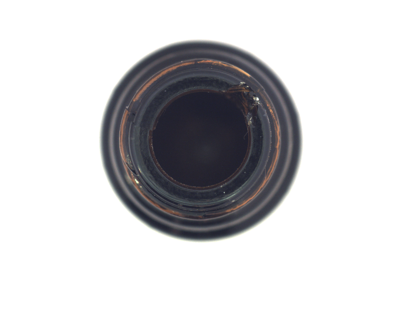

for k = 1:height(testDataTbl)
    I = imread(testDataTbl.imageFilename{k});
    I = imresize(I,inputSize(1:2));
    [bboxes,scores, label] = detect(detector,I);
    I = insertObjectAnnotation(I,'rectangle',bboxes,label);
    figure
    imshow(I)
end

clc;
clear;
close all;

data = load('vehicleTrainingData.mat')

data = struct with fields:
    vehicleTrainingData: [295×2 table]


trainingData = data.vehicleTrainingData

trainingData = 295×2 table
           imageFilename                vehicle     
    ____________________________    ________________

    {'vehicles/image_00001.jpg'}    {[126 78 20 16]}
    {'vehicles/image_00002.jpg'}    {[100 72 35 26]}
    {'vehicles/image_00003.jpg'}    {[ 62 69 26 19]}
    {'vehicles/image_00004.jpg'}    {[ 71 64 22 21]}
    {'vehicles/image_00005.jpg'}    {[147 71 25 18]}
    {'vehicles/image_00006.jpg'}    {[208 62 17 19]}
    {'vehicles/image_00007.jpg'}    {[103 71 31 27]}
    {'vehicles/image_00008.jpg'}    {[102 73 23 20]}
    {'vehicles/image_00009.jpg'}    {[ 98 69 22 18]}
    {'vehicles/image_00010.jpg'}    {[ 97 67 25 22]}
    {'vehicles/image_00011.jpg'}    {[ 94 66 33 28]}
    {'vehicles/image_00012.jpg'}    {[ 96 70 28 23]}
    {'vehicles/image_00013.jpg'}    {[ 99 71 32 23]}
    {'vehicles/image_00014.jpg'}    {[ 92 70 21 16]}
    {'vehicles/image_00015.jpg'}    {[ 92 70 21 17]}
   

trainingData(:,2:end)

ans = 295×1 table
        vehicle     
    ________________

    {[126 78 20 16]}
    {[100 72 35 26]}
    {[ 62 69 26 19]}
    {[ 71 64 22 21]}
    {[147 71 25 18]}
    {[208 62 17 19]}
    {[103 71 31 27]}
    {[102 73 23 20]}
    {[ 98 69 22 18]}
    {[ 97 67 25 22]}
    {[ 94 66 33 28]}
    {[ 96 70 28 23]}
    {[ 99 71 32 23]}
    {[ 92 70 21 16]}
    {[ 92 70 21 17]}
    {[102 69 27 19]}



%trainingData = imageDatastore(trainingData{:,'imageFilename'})
imageDatastore("/Users/frederikplahl/mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png")

ans =   ImageDatastore with properties:

                       Files: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small/019.png'
                              }
                     Folders: {
                              ' .../mvtec_anomaly_detection/00_data/bottle/test/broken_small'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


clc;
clear;
close all;

img = imread("00_data/bottle/ground_truth/broken_large/000_mask.png");
A = {[1 1 1 1];[2 2 2 2]}

A = 2×1 cell array
    {[1 1 1 1]}
    {[2 2 2 2]}


B = {"a";"b";"c"}

B = 3×1 cell array
    {["a"]}
    {["b"]}
    {["c"]}


region = regionprops(img)

region = 255×1 struct array with fields:
    Area
    Centroid
    BoundingBox


for field = 1:length(region)
    if region(field).Area > 0
        A{end+1} = region(field).BoundingBox
        %a = region(field).BoundingBox
    end
end

A = 3×1 cell array
    {[                  1 1 1 1]}
    {[                  2 2 2 2]}
    {[350.5000 284.5000 421 536]}


t = table(A)

t = 3×1 table
                  A              
    _____________________________

    {[                  1 1 1 1]}
    {[                  2 2 2 2]}
    {[350.5000 284.5000 421 536]}


clc;
clear;
close all;

material = ["bottle", "cable", "capsule", "carpet", "grid", "hazelnut", "leather", "metal_nut", "pill", "screw", "tile", "toothbrush", "transistor", "wood", "zipper"];

% Create structs for each element with names and multiple imds
for counter = 1:length(material)
    error = {};
    maskFilename = {};
    wrongImages = {};
    allImages = {};

    element(counter).name = material(counter);
    
    imdsMask = imageDatastore("00_data/"+element(counter).name+"/ground_truth/", "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");
    imdsAllImages = imageDatastore("00_data/"+element(counter).name+"/test/","FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames");
    
    
    for i = 1:length(imdsAllImages.Files)
        if imdsAllImages.Labels(i)=="good"
            wrongImages{end+1,1} = string(imdsAllImages.Files(i));
        end
        allImages{end+1,1} = string(imdsAllImages.Files(i));
    end
    
    for k = 1:length(allImages)
        for j = 1:length(wrongImages)
            if k>length(allImages)
                break
            end
            if string(allImages(k,1))==string(wrongImages(j,1))
                allImages(k,:) = [];
            end
        end
    end
         
    
    
    
    for size = 1:length(imdsMask.Files)
        region = regionprops(imread(imdsMask.Files{size,1}));
        region_table = struct2table(region);
        for field = 1:length(region)
            if region(field).Area > 0
                error{end+1,1} = region(field).BoundingBox;
            end
        end
        maskFilename(size, 1) = imdsMask.Files(size);
    end
    element(counter).data = table(error);
    element(counter).data.maskFilename = maskFilename;
    element(counter).data.imageFilename = allImages;
    
    rng(0);
    shuffledData = element(counter).data;
    shuffledIdx = randperm(height(shuffledData));
    shuffledData = shuffledData(shuffledIdx,:);
    
    % Train Test Split
    cv = cvpartition(height(shuffledData),'HoldOut',0.2);
    idx = cv.test;
    trainingDataTbl = shuffledData(~idx,:);
    testDataTbl  = shuffledData(idx,:);

end
% save("element.mat","element")
element.data

ans = 63×3 table
                error                                                             maskFilename                                                                                        imageFilename                                       
    _____________________________    ______________________________________________________________________________________________________    ___________________________________________________________________________________________

    {[350.5000 284.5000 421 536]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\bottle\ground_truth\broken_large\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\bottle\test\broken_large\000.png"]}
    {[129.5000 388.5000 611 376]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\bottle\ground_truth\broken_large\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_an

ans = 92×3 table
                error                                                           maskFilename                                                                                     imageFilename                                      
    _____________________________    ___________________________________________________________________________________________________    ________________________________________________________________________________________

    {[211.5000 456.5000 288 222]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\cable\ground_truth\bent_wire\000_mask.png' }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\cable\test\bent_wire\000.png" ]}
    {[369.5000 569.5000 176 141]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\cable\ground_truth\bent_wire\001_mask.png' }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_da

ans = 109×3 table
                error                                                          maskFilename                                                                                  imageFilename                                    
    _____________________________    ________________________________________________________________________________________________    _____________________________________________________________________________________

    {[ 714.5000 601.5000 173 23]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\capsule\ground_truth\crack\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\capsule\test\crack\000.png"]}
    {[ 90.5000 458.5000 422 153]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\capsule\ground_truth\crack\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\capsule\test\crac

ans = 89×3 table
                error                                                         maskFilename                                                                                 imageFilename                                    
    _____________________________    _______________________________________________________________________________________________    ____________________________________________________________________________________

    {[134.5000 503.5000 261 300]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\carpet\ground_truth\color\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\carpet\test\color\000.png"]}
    {[301.5000 584.5000 208 201]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\carpet\ground_truth\color\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\carpet\test\color\001.png

ans = 57×3 table
                error                                                         maskFilename                                                                                imageFilename                                   
    _____________________________    ______________________________________________________________________________________________    ___________________________________________________________________________________

    {[247.5000 289.5000 573 502]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\grid\ground_truth\bent\000_mask.png'  }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\grid\test\bent\000.png"  ]}
    {[445.5000 448.5000 323 384]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\grid\ground_truth\bent\001_mask.png'  }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\grid\test\bent\001.png"  ]}
    

ans = 70×3 table
                error                                                          maskFilename                                                                                   imageFilename                                     
    _____________________________    _________________________________________________________________________________________________    ______________________________________________________________________________________

    {[246.5000 270.5000 567 268]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\hazelnut\ground_truth\crack\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\hazelnut\test\crack\000.png"]}
    {[538.5000 337.5000 322 372]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\hazelnut\ground_truth\crack\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\hazelnut\te

ans = 92×3 table
                error                                                          maskFilename                                                                                  imageFilename                                    
    _____________________________    ________________________________________________________________________________________________    _____________________________________________________________________________________

    {[ 691.5000 531.5000 68 107]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\leather\ground_truth\color\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\leather\test\color\000.png"]}
    {[ 656.5000 362.5000 82 127]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\leather\ground_truth\color\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\leather\test\color

ans = 93×3 table
                error                                                          maskFilename                                                                                   imageFilename                                     
    _____________________________    _________________________________________________________________________________________________    ______________________________________________________________________________________

    {[ 245.5000 37.5000 422 377]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\metal_nut\ground_truth\bent\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\metal_nut\test\bent\000.png"]}
    {[ 411.5000 562.5000 142 91]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\metal_nut\ground_truth\bent\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\metal_nut\t

ans = 141×3 table
                error                                                        maskFilename                                                                               imageFilename                                   
    _____________________________    _____________________________________________________________________________________________    __________________________________________________________________________________

    {[  577.5000 418.5000 24 25]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\pill\ground_truth\color\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\pill\test\color\000.png"]}
    {[534.5000 347.5000 126 104]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\pill\ground_truth\color\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\pill\test\color\001.png"]}
    {[499.5

ans = 119×3 table
                error                                                               maskFilename                                                                                            imageFilename                                         
    _____________________________    __________________________________________________________________________________________________________    _______________________________________________________________________________________________

    {[  163.5000 856.5000 98 85]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\screw\ground_truth\manipulated_front\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\screw\test\manipulated_front\000.png"]}
    {[  785.5000 829.5000 76 85]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\screw\ground_truth\manipulated_front\001_mask.png'}    {["

ans = 84×3 table
               error                                                       maskFilename                                                                               imageFilename                                   
    ___________________________    _____________________________________________________________________________________________    __________________________________________________________________________________

    {[198.5000 0.5000 642 840]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\tile\ground_truth\crack\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\tile\test\crack\000.png"]}
    {[ 88.5000 0.5000 538 840]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\tile\ground_truth\crack\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\tile\test\crack\001.png"]}
    {[ 19.5000 0.500

ans = 30×3 table
                error                                                             maskFilename                                                                                         imageFilename                                        
    _____________________________    _______________________________________________________________________________________________________    ____________________________________________________________________________________________

    {[243.5000 203.5000 346 470]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\toothbrush\ground_truth\defective\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\toothbrush\test\defective\000.png"]}
    {[426.5000 261.5000 130 128]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\toothbrush\ground_truth\defective\001_mask.png'}    {["C:\Users\XrStudenten\m

ans = 40×3 table
                error                                                             maskFilename                                                                                         imageFilename                                        
    _____________________________    _______________________________________________________________________________________________________    ____________________________________________________________________________________________

    {[ 239.5000 829.5000 51 118]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\transistor\ground_truth\bent_lead\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\transistor\test\bent_lead\000.png"]}
    {[  701.5000 834.5000 45 62]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\transistor\ground_truth\bent_lead\001_mask.png'}    {["C:\Users\XrStudenten\m

ans = 60×3 table
                error                                                          maskFilename                                                                                  imageFilename                                    
    _____________________________    ________________________________________________________________________________________________    _____________________________________________________________________________________

    {[190.5000 258.5000 561 483]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\wood\ground_truth\color\000_mask.png'   }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\wood\test\color\000.png"   ]}
    {[267.5000 117.5000 503 399]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\wood\ground_truth\color\001_mask.png'   }    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\wood\test\color\00

ans = 119×3 table
                error                                                             maskFilename                                                                                        imageFilename                                       
    _____________________________    ______________________________________________________________________________________________________    ___________________________________________________________________________________________

    {[453.5000 107.5000 142 805]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\zipper\ground_truth\broken_teeth\000_mask.png'}    {["C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\zipper\test\broken_teeth\000.png"]}
    {[ 428.5000 6.5000 126 1018]}    {'C:\Users\XrStudenten\mvtec_anomaly_detection\00_data\zipper\ground_truth\broken_teeth\001_mask.png'}    {["C:\Users\XrStudenten\mvtec_a

function data = augmentData(data)
% Randomly flip images and bounding boxes horizontally.
tform = randomAffine2d('XReflection',true);
sz = size(data{1});
rout = affineOutputView(sz,tform);
data{1} = imwarp(data{1},tform,'OutputView',rout);

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Warp boxes.
data{2} = bboxwarp(data{2},tform,rout);
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Resize boxes.
data{2} = bboxresize(data{2},scale);
end